# TOFマップ作成 Group1

clear; close all;
for i = 1:5
    cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_02_28_-kwave');
    myfilename = sprintf('2018_04_26_Group1ERate5IRate02Num%d', i);
    cd(myfilename);
    load('kgrid.mat')
    load('rfdata.mat')
    tof_data = get_tof_AIC_from_singleRFData(rfdata,kgrid,75);
    cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_04_27_analyzeLipidModel')
    myfilename = sprintf('2018_04_27_TOFdata_Group1ERate5IRate02Num%d', i);
    save(myfilename,'tof_data');
    clear; close all;
end
for i = 1:4
    cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_02_28_-kwave');
    myfilename = sprintf('2018_04_26_Group1ERate%dIRate02Num3', i);
    cd(myfilename);
    load('kgrid.mat')
    load('rfdata.mat')
    tof_data = get_tof_AIC_from_singleRFData(rfdata,kgrid,75);
    cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_04_27_analyzeLipidModel')
    myfilename = sprintf('2018_04_27_TOFdata_Group1ERate%dIRate02Num3', i);
    save(myfilename,'tof_data');
    clear; close all;
end
for i = 4:2:8
    cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_02_28_-kwave');
    myfilename = sprintf('2018_04_26_Group1ERate5IRate0%dNum3', i);
    cd(myfilename);
    load('kgrid.mat')
    load('rfdata.mat')
    tof_data = get_tof_AIC_from_singleRFData(rfdata,kgrid,75);
    cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_04_27_analyzeLipidModel')
    myfilename = sprintf('2018_04_27_TOFdata_Group1ERate5IRate0%dNum3', i);
    save(myfilename,'tof_data');
    clear; close all;
end

cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_02_28_-kwave');
myfilename = sprintf('2018_04_26_Group1ERate5IRate10Num3');
cd(myfilename);
load('kgrid.mat')
load('rfdata.mat')
tof_data = get_tof_AIC_from_singleRFData(rfdata,kgrid,75);
cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_04_27_analyzeLipidModel')
myfilename = sprintf('2018_04_27_TOFdata_Group1ERate5IRate10Num3');
save(myfilename,'tof_data');
clear; close all;

## 平均音速算出(配列定義) Group1

clear; close all;
tof_cell  = zeros(200,100,5,5,5);%{Receiver, Transmitter, ERate, IRate, Num, }
aveSOS = zeros(5,5,5);%{ERate, IRate, Num}
for i = 1:5
    cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_04_27_analyzeLipidModel')
    myfilename = sprintf('2018_04_27_TOFdata_Group1ERate5IRate02Num%d', i);
    load(myfilename,'tof_data');
    tof_cell(:,:,5,1,i) = tof_data;
end
for i = 1:4
    cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_04_27_analyzeLipidModel')
    myfilename = sprintf('2018_04_27_TOFdata_Group1ERate%dIRate02Num3', i);
    load(myfilename,'tof_data');
    tof_cell(:,:,i,1,3) = tof_data;
end
for i = 4:2:8
    cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_04_27_analyzeLipidModel')
    myfilename = sprintf('2018_04_27_TOFdata_Group1ERate5IRate0%dNum3', i);
    load(myfilename,'tof_data');
    tof_cell(:,:,5,i/2,3) = tof_data;
end
cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_04_27_analyzeLipidModel')
myfilename = sprintf('2018_04_27_TOFdata_Group1ERate5IRate10Num3');
load(myfilename,'tof_data');
tof_cell(:,:,5,5,3) = tof_data;
myfilename = sprintf('2018_04_27_Group1allTOFdata_matrix');
save(myfilename,'tof_cell');

## 平均音速算出（メイン） Group1

cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_04_27_analyzeLipidModel')
myfilename = sprintf('2018_04_27_Group1allTOFdata_matrix');
load(myfilename,'tof_cell');
cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_02_28_-kwave');
myfilename = sprintf('2018_04_26_Group1ERate5IRate02Num3');
cd(myfilename);
load('kgrid.mat')
param = makeParam( 0.125,0.125,400,400,0 );
param.source.point_map = cast(linspace(1,100,100),'int8');
t_size = 40.e-3;
t_num = 200;%トランスデューサ数
t_pos = zeros(2, t_num);%センサ位置
t_pos(1,1:t_num/2) = -t_size/2:t_size/(t_num/2-1):t_size/2 ;%素子水平方向距離[m]
t_pos(2,1:t_num/2) = t_size/2;
t_pos(1,t_num/2+1:t_num) = t_pos(1,1:t_num/2);
t_pos(2,t_num/2+1:t_num) = -t_size/2;
sensor.mask=t_pos;
leng = zeros(1,100);
for i = 1:5
    [Min,ind]= min(tof_cell(101:end,:,i,1,3));
    ind = ind+100;
    for j = 1: t_num/2
        leng(1,j) = norm(t_pos(:,j)-t_pos(:,ind(1,j)));
    end
    aveSOS(i,1,3) = mean(leng./Min);
end
for i = 1:5
    if i == 3
        continue
    end
    [Min,ind]= min(tof_cell(101:end,:,5,1,i));
    ind = ind+100;
    for j = 1: t_num/2
        leng(1,j) = norm(t_pos(:,j)-t_pos(:,ind(1,j)));
    end
    aveSOS(5,1,i) = mean(leng./Min);
end
for i = 2:5
    [Min,ind]= min(tof_cell(101:end,:,5,i,3));
    ind = ind+100;
    for j = 1: t_num/2
        leng(1,j) = norm(t_pos(:,j)-t_pos(:,ind(1,j)));
    end
    aveSOS(5,i,3) = mean(leng./Min);
end
cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_04_27_analyzeLipidModel')
myfilename = sprintf('2018_04_28_Group1aveSOS');
save(myfilename,'aveSOS');

## TOFマップ作成

%Group2
clear; close all;
for i = 1:5
    cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_02_28_-kwave');
    myfilename = sprintf('2018_04_26_Group2ERate5IRate02Num%d', i);
    cd(myfilename);
    load('kgrid.mat')
    load('rfdata.mat')
    tof_data = get_tof_AIC_from_singleRFData(rfdata,kgrid,75);
    cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_04_27_analyzeLipidModel')
    myfilename = sprintf('2018_04_27_TOFdata_Group2ERate5IRate02Num%d', i);
    save(myfilename,'tof_data');
    clear; close all;
end
for i = 1:4
    cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_02_28_-kwave');
    myfilename = sprintf('2018_04_26_Group2ERate%dIRate02Num3', i);
    cd(myfilename);
    load('kgrid.mat')
    load('rfdata.mat')
    tof_data = get_tof_AIC_from_singleRFData(rfdata,kgrid,75);
    cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_04_27_analyzeLipidModel')
    myfilename = sprintf('2018_04_27_TOFdata_Group2ERate%dIRate02Num3', i);
    save(myfilename,'tof_data');
    clear; close all;
end
for i = 4:2:8
    cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_02_28_-kwave');
    myfilename = sprintf('2018_04_26_Group2ERate5IRate0%dNum3', i);
    cd(myfilename);
    load('kgrid.mat')
    load('rfdata.mat')
    tof_data = get_tof_AIC_from_singleRFData(rfdata,kgrid,75);
    cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_04_27_analyzeLipidModel')
    myfilename = sprintf('2018_04_27_TOFdata_Group2ERate5IRate0%dNum3', i);
    save(myfilename,'tof_data');
    clear; close all;
end

cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_02_28_-kwave');
myfilename = sprintf('2018_04_26_Group2ERate5IRate10Num3');
cd(myfilename);
load('kgrid.mat')
load('rfdata.mat')
tof_data = get_tof_AIC_from_singleRFData(rfdata,kgrid,75);
cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_04_27_analyzeLipidModel')
myfilename = sprintf('2018_04_27_TOFdata_Group2ERate5IRate10Num3');
save(myfilename,'tof_data');
clear; close all;

## 平均音速算出(配列定義) Group2

clear; close all;
tof_cell  = zeros(200,100,5,5,5);%{Receiver, Transmitter, ERate, IRate, Num, }
aveSOS = zeros(5,5,5);%{ERate, IRate, Num}
for i = 1:5
    cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_04_27_analyzeLipidModel')
    myfilename = sprintf('2018_04_27_TOFdata_Group2ERate5IRate02Num%d', i);
    load(myfilename,'tof_data');
    tof_cell(:,:,5,1,i) = tof_data;
end
for i = 1:4
    cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_04_27_analyzeLipidModel')
    myfilename = sprintf('2018_04_27_TOFdata_Group2ERate%dIRate02Num3', i);
    load(myfilename,'tof_data');
    tof_cell(:,:,i,1,3) = tof_data;
end
for i = 4:2:8
    cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_04_27_analyzeLipidModel')
    myfilename = sprintf('2018_04_27_TOFdata_Group2ERate5IRate0%dNum3', i);
    load(myfilename,'tof_data');
    tof_cell(:,:,5,i/2,3) = tof_data;
end
cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_04_27_analyzeLipidModel')
myfilename = sprintf('2018_04_27_TOFdata_Group2ERate5IRate10Num3');
load(myfilename,'tof_data');
tof_cell(:,:,5,5,3) = tof_data;
myfilename = sprintf('2018_04_27_Group2allTOFdata_matrix');
save(myfilename,'tof_cell');

## 平均音速算出（メイン）Group2

cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_04_27_analyzeLipidModel')
myfilename = sprintf('2018_04_27_Group2allTOFdata_matrix');
load(myfilename,'tof_cell');
cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_02_28_-kwave');
myfilename = sprintf('2018_04_26_Group2ERate5IRate02Num3');
cd(myfilename);
load('kgrid.mat')
param = makeParam( 0.125,0.125,400,400,0 );
param.source.point_map = cast(linspace(1,100,100),'int8');
t_size = 40.e-3;
t_num = 200;%トランスデューサ数
t_pos = zeros(2, t_num);%センサ位置
t_pos(1,1:t_num/2) = -t_size/2:t_size/(t_num/2-1):t_size/2 ;%素子水平方向距離[m]
t_pos(2,1:t_num/2) = t_size/2;
t_pos(1,t_num/2+1:t_num) = t_pos(1,1:t_num/2);
t_pos(2,t_num/2+1:t_num) = -t_size/2;
sensor.mask=t_pos;
leng = zeros(1,100);
for i = 1:5
    [Min,ind]= min(tof_cell(101:end,:,i,1,3));
    ind = ind+100;
    for j = 1: t_num/2
        leng(1,j) = norm(t_pos(:,j)-t_pos(:,ind(1,j)));
    end
    aveSOS(i,1,3) = mean(leng./Min);
end
for i = 1:5
    if i == 3
        continue
    end
    [Min,ind]= min(tof_cell(101:end,:,5,1,i));
    ind = ind+100;
    for j = 1: t_num/2
        leng(1,j) = norm(t_pos(:,j)-t_pos(:,ind(1,j)));
    end
    aveSOS(5,1,i) = mean(leng./Min);
end
for i = 2:5
    [Min,ind]= min(tof_cell(101:end,:,5,i,3));
    ind = ind+100;
    for j = 1: t_num/2
        leng(1,j) = norm(t_pos(:,j)-t_pos(:,ind(1,j)));
    end
    aveSOS(5,i,3) = mean(leng./Min);
end
cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_04_27_analyzeLipidModel')
myfilename = sprintf('2018_04_28_Group2aveSOS');
save(myfilename,'aveSOS');

## Group1,Group2のaveSOSを平均してみる．

%ねらい：結果の非線形さがモデルのランダムさによらず同じ傾向を示すのならば，
%             算出アルゴリズムになにか誤りがあるのではないかと疑えるので検証する
%計算
cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_04_27_analyzeLipidModel')
load('2018_04_28_Group1aveSOS.mat')
aveSOS_Gr1 = aveSOS;
load('2018_04_28_Group2aveSOS.mat')
aveSOS_Gr2 = aveSOS;
aveSOS_Gr1_Gr2 = (aveSOS_Gr1 + aveSOS_Gr2) /2;
%グラフ作成
figure;
plot(aveSOS_Gr1_Gr2(:,1,3));

## make figure置き場　[2018-04-30]

aveSOS_num =  zeros(1,5);
aveSOS_num(1,:) = aveSOS(5,1,:);
figure;
plot(aveSOS_num);
xlabel('EMCLの個数');
ylabel('平均音速[m/s]')
exportfig('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_04_27_analyzeLipidModel\Group1aveSOS_num','png',[300,200]);

aveSOS_EMCLrate = zeros(1,5);
aveSOS_EMCLrate(1,:) = aveSOS(:,1,3);
figure;
plot(aveSOS_EMCLrate);
xlabel('EMCLの占有率[%]');
ylabel('平均音速[m/s]')
exportfig('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_04_27_analyzeLipidModel\Group1aveSOS_EMCLrate','png',[300,200]);

aveSOS_IMCLrate = zeros(1,5);
aveSOS_IMCLrate(1,:) = aveSOS(5,:,3);
figure;
x = [ 0.1 0.2 0.3 0.4 0.5 ];
plot(x,aveSOS_IMCLrate);
xlabel('IMCLの占有率[%]');
ylabel('平均音速[m/s]')
exportfig('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_04_27_analyzeLipidModel\Group1aveSOS_IMCLrate','png',[300,200]);

aveSOS_num =  zeros(1,5);
aveSOS_num(1,:) = aveSOS(5,1,:);
figure;
plot(aveSOS_num);
xlabel('EMCLの個数');
ylabel('平均音速[m/s]')
exportfig('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_04_27_analyzeLipidModel\Group2aveSOS_num','png',[300,200]);
aveSOS_EMCLrate = zeros(1,5);
aveSOS_EMCLrate(1,:) = aveSOS(:,1,3);
figure;
plot(aveSOS_EMCLrate);
xlabel('EMCLの占有率[%]');
ylabel('平均音速[m/s]')
exportfig('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_04_27_analyzeLipidModel\Group2aveSOS_EMCLrate','png',[300,200]);

aveSOS_IMCLrate = zeros(1,5);
aveSOS_IMCLrate(1,:) = aveSOS(5,:,3);
figure;
x = [ 0.1 0.2 0.3 0.4 0.5 ];
plot(x,aveSOS_IMCLrate);
xlabel('IMCLの占有率[%]');
ylabel('平均音速[m/s]')
exportfig('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_04_27_analyzeLipidModel\Group2aveSOS_IMCLrate','png',[300,200]);


aveSOS_num =  zeros(1,5);
aveSOS_num(1,:) = aveSOS(5,1,:);
figure;
plot(aveSOS_num);
xlabel('EMCLの個数');
ylabel('平均音速[m/s]')
exportfig('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_04_27_analyzeLipidModel\Group1&2aveSOS_num','png',[300,200]);
aveSOS_EMCLrate = zeros(1,5);
aveSOS_EMCLrate(1,:) = aveSOS(:,1,3);
figure;
plot(aveSOS_EMCLrate);
xlabel('EMCLの占有率[%]');
ylabel('平均音速[m/s]')
exportfig('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_04_27_analyzeLipidModel\Group1&2aveSOS_EMCLrate','png',[300,200]);

aveSOS_IMCLrate = zeros(1,5);
aveSOS_IMCLrate(1,:) = aveSOS(5,:,3);
figure;
x = [ 0.1 0.2 0.3 0.4 0.5 ];
plot(x,aveSOS_IMCLrate);
xlabel('IMCLの占有率[%]');
ylabel('平均音速[m/s]')
exportfig('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_04_27_analyzeLipidModel\Group1&2aveSOS_IMCLrate','png',[300,200]);

## EMCLの占有率を1,2,3,4,5,6,8,10,12,14,16,18,20%と振った場合

aveSOS_EMCLrate = zeros(1,20);
aveSOS_EMCLrate(1,:) = aveSOS(:,1,3);
figure;
x = [2 4 6 8 10 12 14 16 18 20];
plot(x(1,1:end),aveSOS_EMCLrate(1,2:2:20));
xlabel('EMCLの占有率[%]');
ylabel('平均音速[m/s]')
exportfig('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_04_27_analyzeLipidModel\Group1aveSOS_expand_EMCLrate','png',[300,200]);

## 可視化段階

%subplotを想定．mediumとTOFマップ（最短到達時間ポイントに大きな値を埋め込んで図を見やすくする役割）
% 対象はGroup1に限定

param = makeParam( 0.125,0.125,400,400,0 );
kgrid = makeGrid(param.grid.Nx, param.grid.dx, param.grid.Ny, param.grid.dy);
for i = 1:5
    figure;
    cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\medium\2018_04_26_randomScatter')
    myfilename = sprintf('Group1ERate%dIRate02Num3', i);
    load(myfilename);
    subplot(1,2,1);
    imagesc(kgrid.x_vec*1000,kgrid.y_vec*1000,medium.sound_speed);
    axis equal
    axis tight
    hold on
    scatter(t_pos(2,:)*1000,t_pos(1,:)*1000,'rs','filled');
    xlabel('y-axis[mm]')
    ylabel('x-axis[mm]')
    hold off
    subplot(1,2,2);
    cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_04_27_analyzeLipidModel')
    myfilename = sprintf('2018_04_27_TOFdata_Group1ERate%dIRate02Num3',i);
    load(myfilename)
    [Min,ind]= min(tof_data(101:end,:));
    ind = ind+100;
    for j = 1:100
        tof_data(ind(1,j),j) = 0;
    end
    imagesc(1:100,1:100,tof_data(101:end,:));
    xlabel('receiver')
    ylabel('transimitter')
    axis tight
    axis equal
    titlename = sprintf('Group1ERate%dIRate02Num3',i);
    axes;
    title(titlename);
    axis off;
    cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_04_27_analyzeLipidModel')
    myfilename = sprintf('2018_05_01_Group1ERate%dIRate02Num3_Compare',i);
    exportfig(myfilename,'png',[400,180]);
end

for i = 1:5
    figure;
    cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\medium\2018_04_26_randomScatter')
    myfilename = sprintf('Group1ERate5IRate02Num%d', i);
    load(myfilename);
    subplot(1,2,1);
    imagesc(kgrid.x_vec*1000,kgrid.y_vec*1000,medium.sound_speed);
    axis equal
    axis tight
    hold on
    scatter(t_pos(2,:)*1000,t_pos(1,:)*1000,'rs','filled');
    xlabel('y-axis[mm]')
    ylabel('x-axis[mm]')
    hold off
    subplot(1,2,2);
    cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_04_27_analyzeLipidModel')
    myfilename = sprintf('2018_04_27_TOFdata_Group1ERate5IRate02Num%d',i);
    load(myfilename)
    [Min,ind]= min(tof_data(101:end,:));
    ind = ind+100;
    for j = 1:100
        tof_data(ind(1,j),j) = 0;
    end
    imagesc(1:100,1:100,tof_data(101:end,:));
    xlabel('receiver')
    ylabel('transimitter')
    axis tight
    axis equal
    titlename = sprintf('Group1ERate5IRate02Num%d',i);
    axes;
    title(titlename);
    axis off;
    cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_04_27_analyzeLipidModel')
    myfilename = sprintf('2018_05_01_Group1ERate5IRate02Num%d_Compare',i);
    exportfig(myfilename,'png',[400,180]);
end

for i = 1:5
    figure;
    cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\medium\2018_04_26_randomScatter')
    myfilename = sprintf('Group1ERate5IRate%02dNum3', 2*i);
    load(myfilename);
    subplot(1,2,1);
    imagesc(kgrid.x_vec*1000,kgrid.y_vec*1000,medium.sound_speed);
    axis equal
    axis tight
    hold on
    scatter(t_pos(2,:)*1000,t_pos(1,:)*1000,'rs','filled');
    xlabel('y-axis[mm]')
    ylabel('x-axis[mm]')
    hold off
    subplot(1,2,2);
    cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_04_27_analyzeLipidModel')
    myfilename = sprintf('2018_04_27_TOFdata_Group1ERate5IRate%02dNum3',i*2);
    load(myfilename)
    [Min,ind]= min(tof_data(101:end,:));
    ind = ind+100;
    for j = 1:100
        tof_data(ind(1,j),j) = 0;
    end
    imagesc(1:100,1:100,tof_data(101:end,:));
    xlabel('receiver')
    ylabel('transimitter')
    axis tight
    axis equal
    titlename = sprintf('Group1ERate5IRate%02dNum3',i*2);
    axes;
    title(titlename);
    axis off;
    cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_04_27_analyzeLipidModel')
    myfilename = sprintf('2018_05_01_Group1ERate5IRate%02dNum3_Compare',i);
    exportfig(myfilename,'png',[400,180]);
end

for i = 2:4:20
    figure;
    cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\medium\2018_04_26_randomScatter')
    myfilename = sprintf('Group1ERate%dIRate02Num3', i);
    load(myfilename);
    subplot(1,2,1);
    imagesc(kgrid.x_vec*1000,kgrid.y_vec*1000,medium.sound_speed);
    axis equal
    axis tight
    hold on
    scatter(t_pos(2,:)*1000,t_pos(1,:)*1000,'rs','filled');
    xlabel('y-axis[mm]')
    ylabel('x-axis[mm]')
    hold off
    subplot(1,2,2);
    cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_04_27_analyzeLipidModel')
    myfilename = sprintf('2018_04_27_TOFdata_Group1ERate%dIRate02Num3',i);
    load(myfilename)
    [Min,ind]= min(tof_data(101:end,:));
    ind = ind+100;
    for j = 1:100
        tof_data(ind(1,j),j) = 0;
    end
    imagesc(1:100,1:100,tof_data(101:end,:));
    xlabel('receiver')
    ylabel('transimitter')
    axis tight
    axis equal
    titlename = sprintf('Group1ERate%dIRate02Num3',i);
    axes;
    title(titlename);
    axis off;
    cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_04_27_analyzeLipidModel')
    myfilename = sprintf('2018_05_01_Group1ERate%dIRate02Num3_Compare',i);
    exportfig(myfilename,'png',[400,180]);
end

## Mediumの作り直し

medium = makeRandomMedium(param,20,3,2);
imagesc(kgrid.x_vec*1000,kgrid.y_vec*1000,medium.sound_speed);
axis equal
axis tight
hold on
scatter(t_pos(2,:)*1000,t_pos(1,:)*1000,'rs','filled');
xlabel('y-axis[mm]')
ylabel('x-axis[mm]')
hold off

## 可視化段階(Group1-2)

%subplotを想定．mediumとTOFマップ（最短到達時間ポイントに大きな値を埋め込んで図を見やすくする役割）
% 対象はGroup1に限定
param = makeParam( 0.125,0.125,400,400,0 );
param.source.point_map = cast(linspace(1,100,100),'int8');
t_size = 40.e-3;
t_num = 200;%トランスデューサ数
t_pos = zeros(2, t_num);%センサ位置
t_pos(1,1:t_num/2) = -t_size/2:t_size/(t_num/2-1):t_size/2 ;%素子水平方向距離[m]
t_pos(2,1:t_num/2) = t_size/2;
t_pos(1,t_num/2+1:t_num) = t_pos(1,1:t_num/2);
t_pos(2,t_num/2+1:t_num) = -t_size/2;
sensor.mask=t_pos;

kgrid = makeGrid(param.grid.Nx, param.grid.dx, param.grid.Ny, param.grid.dy);

         Update codes to use the syntax kgrid = kWaveGrid(...).


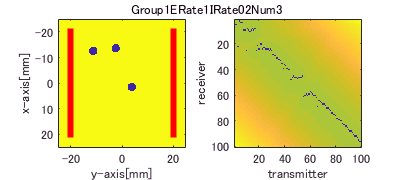

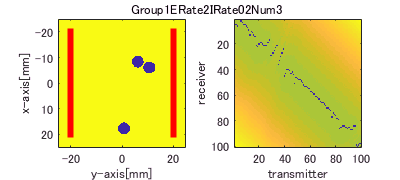

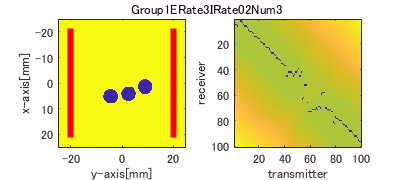

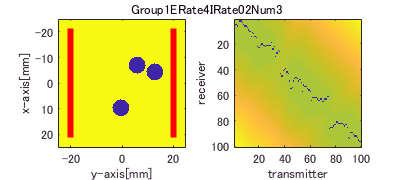

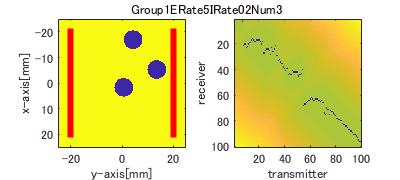

for i = 1:5
    figure;
    cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\medium\2018_04_26_randomScatter')
    myfilename = sprintf('Group1ERate%dIRate02Num3-2', i);
    load(myfilename);
    subplot(1,2,1);
    imagesc(kgrid.x_vec*1000,kgrid.y_vec*1000,medium.sound_speed);
    axis equal
    axis tight
    hold on
    scatter(t_pos(2,:)*1000,t_pos(1,:)*1000,'rs','filled');
    xlabel('y-axis[mm]')
    ylabel('x-axis[mm]')
    hold off
    subplot(1,2,2);
    cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_04_27_analyzeLipidModel')
    myfilename = sprintf('2018_04_27_TOFdata_Group1ERate%dIRate02Num3-2',i);
    load(myfilename)
    [Min,ind]= min(tof_data(101:end,:));
    ind = ind+100;
    for j = 1:100
        tof_data(ind(1,j),j) = 0;
    end
    imagesc(1:100,1:100,tof_data(101:end,:));
    xlabel('transmitter')
    ylabel('receiver')
    axis tight
    axis equal
    titlename = sprintf('Group1ERate%dIRate02Num3',i);
    axes;
    title(titlename);
    axis off;
    cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_04_27_analyzeLipidModel')
    myfilename = sprintf('2018_05_01_Group1ERate%dIRate02Num3_Compare-2',i);
    exportfig(myfilename,'png',[400,180]);
end

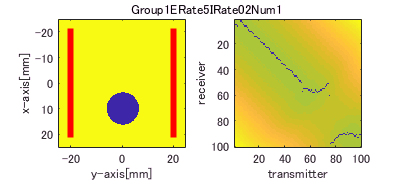

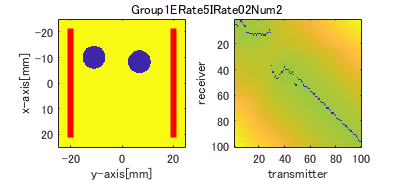

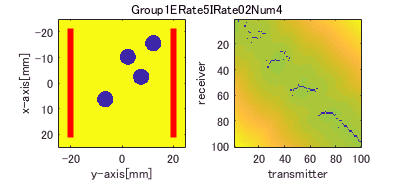

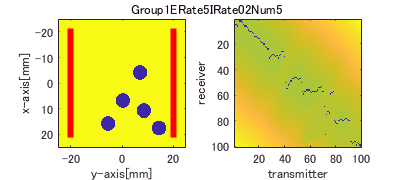


for i = 1:5
    figure;
    cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\medium\2018_04_26_randomScatter')
    myfilename = sprintf('Group1ERate5IRate02Num%d-2', i);
    load(myfilename);
    subplot(1,2,1);
    imagesc(kgrid.x_vec*1000,kgrid.y_vec*1000,medium.sound_speed);
    axis equal
    axis tight
    hold on
    scatter(t_pos(2,:)*1000,t_pos(1,:)*1000,'rs','filled');
    xlabel('y-axis[mm]')
    ylabel('x-axis[mm]')
    hold off
    subplot(1,2,2);
    cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_04_27_analyzeLipidModel')
    myfilename = sprintf('2018_04_27_TOFdata_Group1ERate5IRate02Num%d-2',i);
    load(myfilename)
    [Min,ind]= min(tof_data(101:end,:));
    ind = ind+100;
    for j = 1:100
        tof_data(ind(1,j),j) = 0;
    end
    imagesc(1:100,1:100,tof_data(101:end,:));
    xlabel('transmitter')
    ylabel('receiver')
    axis tight
    axis equal
    titlename = sprintf('Group1ERate5IRate02Num%d',i);
    axes;
    title(titlename);
    axis off;
    cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_04_27_analyzeLipidModel')
    myfilename = sprintf('2018_05_01_Group1ERate5IRate02Num%d_Compare-2',i);
    exportfig(myfilename,'png',[400,180]);
end

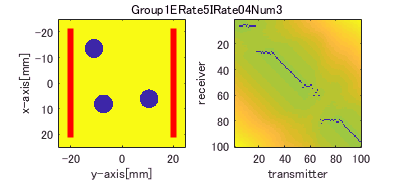

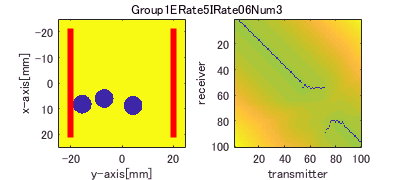

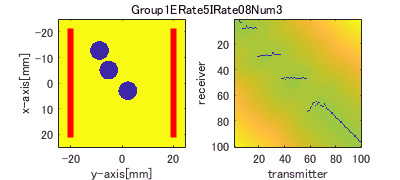

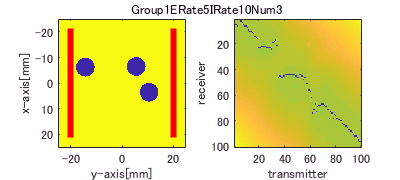


for i = 1:5
    figure;
    cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\medium\2018_04_26_randomScatter')
    myfilename = sprintf('Group1ERate5IRate%02dNum3-2', 2*i);
    load(myfilename);
    subplot(1,2,1);
    imagesc(kgrid.x_vec*1000,kgrid.y_vec*1000,medium.sound_speed);
    axis equal
    axis tight
    hold on
    scatter(t_pos(2,:)*1000,t_pos(1,:)*1000,'rs','filled');
    xlabel('y-axis[mm]')
    ylabel('x-axis[mm]')
    hold off
    subplot(1,2,2);
    cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_04_27_analyzeLipidModel')
    myfilename = sprintf('2018_04_27_TOFdata_Group1ERate5IRate%02dNum3-2',i*2);
    load(myfilename)
    [Min,ind]= min(tof_data(101:end,:));
    ind = ind+100;
    for j = 1:100
        tof_data(ind(1,j),j) = 0;
    end
    imagesc(1:100,1:100,tof_data(101:end,:));
    xlabel('transmitter')
    ylabel('receiver')
    axis tight
    axis equal
    titlename = sprintf('Group1ERate5IRate%02dNum3',i*2);
    axes;
    title(titlename);
    axis off;
    cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_04_27_analyzeLipidModel')
    myfilename = sprintf('2018_05_01_Group1ERate5IRate%02dNum3_Compare-2',i*2);
    exportfig(myfilename,'png',[400,180]);
end

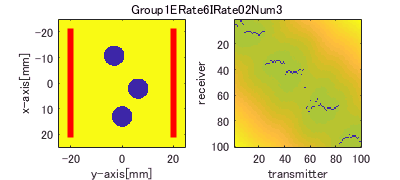

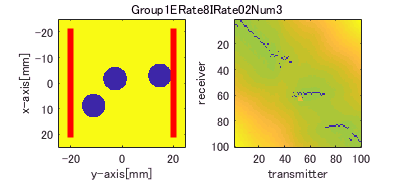

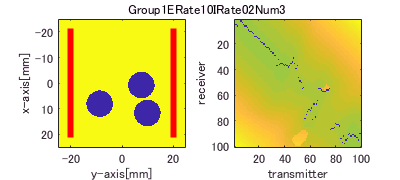

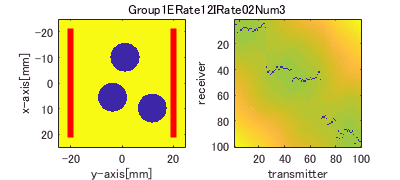

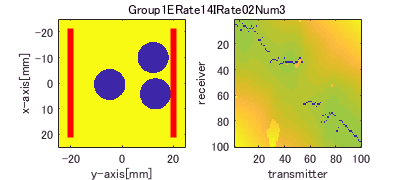

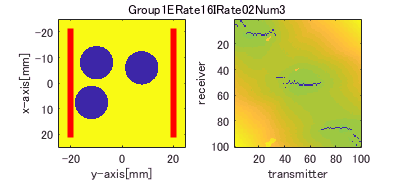

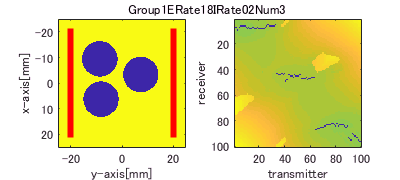

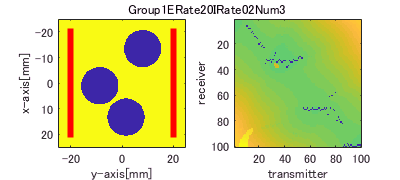


for i = 2:2:20
    figure;
    cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\medium\2018_04_26_randomScatter')
    myfilename = sprintf('Group1ERate%dIRate02Num3-2', i);
    load(myfilename);
    subplot(1,2,1);
    imagesc(kgrid.x_vec*1000,kgrid.y_vec*1000,medium.sound_speed);
    axis equal
    axis tight
    hold on
    scatter(t_pos(2,:)*1000,t_pos(1,:)*1000,'rs','filled');
    xlabel('y-axis[mm]')
    ylabel('x-axis[mm]')
    hold off
    subplot(1,2,2);
    cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_04_27_analyzeLipidModel')
    myfilename = sprintf('2018_04_27_TOFdata_Group1ERate%dIRate02Num3-2',i);
    load(myfilename)
    [Min,ind]= min(tof_data(101:end,:));
    ind = ind+100;
    for j = 1:100
        tof_data(ind(1,j),j) = 0;
    end
    imagesc(1:100,1:100,tof_data(101:end,:));
    xlabel('transmitter')
    ylabel('receiver')
    axis tight
    axis equal
    titlename = sprintf('Group1ERate%dIRate02Num3',i);
    axes;
    title(titlename);
    axis off;
    cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_04_27_analyzeLipidModel')
    myfilename = sprintf('2018_05_01_Group1ERate%dIRate02Num3_Compare-2',i);
    exportfig(myfilename,'png',[400,180]);
end

## make figure置き場　[2018-05-02]

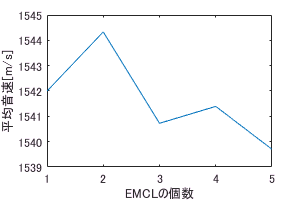

aveSOS_num =  zeros(1,5);
aveSOS_num(1,:) = aveSOS(5,1,:);
figure;
plot(aveSOS_num);
xlabel('EMCLの個数');
ylabel('平均音速[m/s]')
exportfig('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_04_27_analyzeLipidModel\Group1aveSOS_num-2','png',[300,200]);

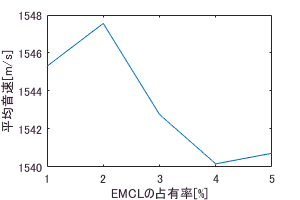


aveSOS_EMCLrate = zeros(1,5);
aveSOS_EMCLrate(1,:) = aveSOS(1:5,1,3);
figure;
plot(aveSOS_EMCLrate);
xlabel('EMCLの占有率[%]');
ylabel('平均音速[m/s]')
exportfig('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_04_27_analyzeLipidModel\Group1aveSOS_EMCLrate-2','png',[300,200]);

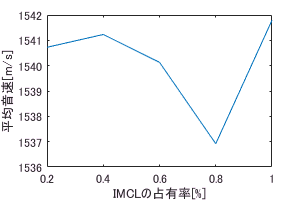


aveSOS_IMCLrate = zeros(1,5);
aveSOS_IMCLrate(1,:) = aveSOS(5,:,3);
figure;
x = [ 0.1 0.2 0.3 0.4 0.5 ];
plot(x*2,aveSOS_IMCLrate);
xlabel('IMCLの占有率[%]');
ylabel('平均音速[m/s]')
exportfig('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_04_27_analyzeLipidModel\Group1aveSOS_IMCLrate-2','png',[300,200]);

## EMCLの占有率を1,2,3,4,5,6,8,10,12,14,16,18,20%と振った場合(first arrival)

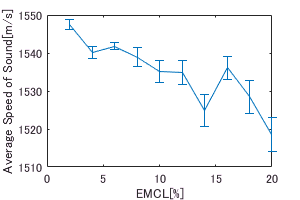

cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_04_27_analyzeLipidModel')
load('2018_04_28_Group1aveSOS_temp-2')
load('2018_04_28_Group1steSOS_temp-2')
aveSOS_EMCLrate = zeros(1,20);
aveSOS_EMCLrate(1,:) = aveSOS(:,1,3);
steSOS_EMCLrate = zeros(1,20);
steSOS_EMCLrate(1,:) = steSOS(:,1,3);
figure;
x = [2 4 6 8 10 12 14 16 18 20];
errorbar(x(1,1:end),aveSOS_EMCLrate(1,2:2:20),2*steSOS_EMCLrate(1,2:2:20));
xlabel('EMCL[%]');
ylabel('Average Speed of Sound[m/s]')
exportfig('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_04_27_analyzeLipidModel\Group1aveSOS_expand_EMCLrate-2withSTE','png',[300,200]);

## 上の振り方のまま別の平均音速算出法を試す．

対向する受信素子において，その伝わるパワーの半分が伝わった時間を元に平均音速を算出する．

cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_02_28_-kwave');
myfilename = sprintf('2018_04_26_Group1ERate5IRate02Num3-2');
cd(myfilename);
load('kgrid.mat')
param = makeParam( 0.125,0.125,400,400,0 );
param.source.point_map = cast(linspace(1,100,100),'int8');
t_size = 40.e-3;
t_num = 200;%トランスデューサ数
t_pos = zeros(2, t_num);%センサ位置
t_pos(1,1:t_num/2) = -t_size/2:t_size/(t_num/2-1):t_size/2 ;%素子水平方向距離[m]
t_pos(2,1:t_num/2) = t_size/2;
t_pos(1,t_num/2+1:t_num) = t_pos(1,1:t_num/2);
t_pos(2,t_num/2+1:t_num) = -t_size/2;
sensor.mask=t_pos;
leng = zeros(1,100);
dt = kgrid.dt;
store_rf = zeros(20,length(rfdata(:,1,1)));
str_rf_abs = zeros(20,length(rfdata(:,1,1)));
cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_02_28_-kwave');
for i = 2:2:20
    myfilename = sprintf('2018_04_26_Group1ERate%dIRate02Num3-2',i);
    cd(myfilename);
    load('rfdata')
    for j = 1: t_num/2
        store_rf(1,i) = rfdata(:,100+j,j);
        
        leng(1,j) = norm(t_pos(:,j)-t_pos(:,ind(1,j)));
    end
    aveSOS(i,1,3) = mean(leng./Min);
    steSOS(i,1,3) = std(leng./Min)/sqrt(t_num/2);
    
end

代入の右辺の次元が、大きさが 1 でない次元の添字より多くなっています

cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_04_27_analyzeLipidModel')
myfilename = sprintf('2018_04_28_Group1aveSOS_temp-2');
save(myfilename,'aveSOS');
myfilename = sprintf('2018_04_28_Group1steSOS_temp-2');
save(myfilename,'steSOS');

上のデータから作図

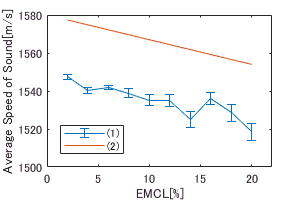

cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_04_27_analyzeLipidModel')
load('2018_04_28_Group1aveSOS_temp-2')
load('2018_04_28_Group1steSOS_temp-2')

aveSOS_EMCLrate = zeros(1,20);
aveSOS_EMCLrate(1,:) = aveSOS(:,1,3);
steSOS_EMCLrate = zeros(1,20);
steSOS_EMCLrate(1,:) = steSOS(:,1,3);
figure;
x = [2 4 6 8 10 12 14 16 18 20];
errorbar(x(1,1:end),aveSOS_EMCLrate(1,2:2:20),2*steSOS_EMCLrate(1,2:2:20));
xlabel('EMCL[%]');
ylabel('Average Speed of Sound[m/s]')
xlim([0 22])
hold on;

% cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_04_27_analyzeLipidModel')
% load('2018_04_28_Group1aveSOS2_temp-2')
% load('2018_04_28_Group1steSOS2_temp-2')
% 
% aveSOS_EMCLrate = zeros(20,1);
% aveSOS_EMCLrate(:,1) = aveSOS(:,1);
% steSOS_EMCLrate = zeros(20,1);
% steSOS_EMCLrate(:,1) = steSOS(:,1);
% errorbar(x(1,1:end),aveSOS_EMCLrate(2:2:20,1),2*steSOS_EMCLrate(2:2:20,1));
% 
v_muscle = 1580;%筋肉の音速[m/s]
v_fat = 1450;%脂肪の音速[m/s]
aveSOS_simple = zeros(20,1);
for i = 2:2:20
    aveSOS_simple(i,1) = v_fat*i/100 + v_muscle*(1-i/100);
end
plot(2:2:20,aveSOS_simple(2:2:20));

hold off;
legend('(1)','(2)','Location','southwest')
exportfig('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_04_27_analyzeLipidModel\Group1aveSOS2_expand_EMCLrate-2withSTE','png',[300,200]);

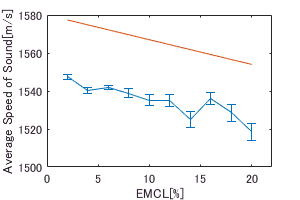

cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_04_27_analyzeLipidModel')
load('2018_04_28_Group1aveSOS_temp-2')
load('2018_04_28_Group1steSOS_temp-2')

aveSOS_EMCLrate = zeros(1,20);
aveSOS_EMCLrate(1,:) = aveSOS(:,1,3);
steSOS_EMCLrate = zeros(1,20);
steSOS_EMCLrate(1,:) = steSOS(:,1,3);
figure;
x = [2 4 6 8 10 12 14 16 18 20];
errorbar(x(1,1:end),aveSOS_EMCLrate(1,2:2:20),2*steSOS_EMCLrate(1,2:2:20));
xlabel('EMCL[%]');
ylabel('Average Speed of Sound[m/s]')
xlim([0 22])
hold on;

% cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_04_27_analyzeLipidModel')
% load('2018_04_28_Group1aveSOS2_temp-2')
% load('2018_04_28_Group1steSOS2_temp-2')
% 
% aveSOS_EMCLrate = zeros(20,1);
% aveSOS_EMCLrate(:,1) = aveSOS(:,1);
% steSOS_EMCLrate = zeros(20,1);
% steSOS_EMCLrate(:,1) = steSOS(:,1);
% errorbar(x(1,1:end),aveSOS_EMCLrate(2:2:20,1),2*steSOS_EMCLrate(2:2:20,1));
% 
v_muscle = 1580;%筋肉の音速[m/s]
v_fat = 1450;%脂肪の音速[m/s]
aveSOS_simple = zeros(20,1);
for i = 2:2:20
    aveSOS_simple(i,1) = v_fat*i/100 + v_muscle*(1-i/100);
end
plot(2:2:20,aveSOS_simple(2:2:20));
hold off;

exportfig('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_04_27_analyzeLipidModel\Group1aveSOS3_expand_EMCLrate-2withSTE','png',[300,200]);

## 送信素子から伝搬した波のうち，初動が最も早い受信素子を基準にして出した平均音速

## この方式で認識した伝播経路を線で結ぶ．

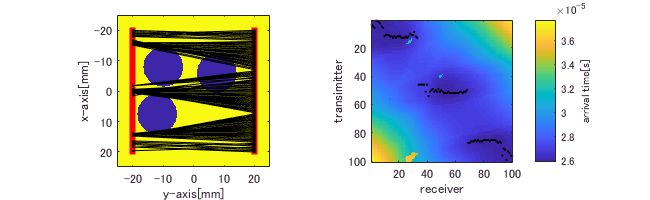

cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_02_28_-kwave');
myfilename = sprintf('2018_04_26_Group1ERate5IRate02Num3-2');
cd(myfilename);
load('kgrid.mat')
i = 16;

figure;
cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\medium\2018_04_26_randomScatter')
myfilename = sprintf('Group1ERate%dIRate02Num3-2', i);
load(myfilename);
cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_04_27_analyzeLipidModel')
myfilename = sprintf('2018_04_27_TOFdata_Group1ERate%dIRate02Num3-2',i);
load(myfilename)


param = makeParam( 0.125,0.125,400,400,0 );
param.source.point_map = cast(linspace(1,100,100),'int8');
t_size = 40.e-3;
t_num = 200;%トランスデューサ数
t_pos = zeros(2, t_num);%センサ位置
t_pos(1,1:t_num/2) = -t_size/2:t_size/(t_num/2-1):t_size/2 ;%素子水平方向距離[m]
t_pos(2,1:t_num/2) = t_size/2;
t_pos(1,t_num/2+1:t_num) = t_pos(1,1:t_num/2);
t_pos(2,t_num/2+1:t_num) = -t_size/2;
sensor.mask=t_pos;


[Min,ind]= min(tof_data(101:end,:));
ind = ind+100;
% for j = 1:100
%     tof_data(ind(1,j),j) = 0;
% end

subplot(1,2,1);
imagesc(kgrid.x_vec*1000,kgrid.y_vec*1000,medium.sound_speed);
axis equal
axis tight
hold on
scatter(t_pos(2,:)*1000,t_pos(1,:)*1000,'rs','filled');
xlabel('y-axis[mm]')
ylabel('x-axis[mm]')

hold on
for i = 1:length(ind)
%     plot([x0;x1],[y0;y1]);
    plot([t_pos(2,i)*1000;t_pos(2,ind(i))*1000],[t_pos(1,i)*1000;t_pos(1,ind(i))*1000],'.-k','LineWidth',0.01);
end

hold off
subplot(1,2,2);


imagesc(1:100,1:100,tof_data(101:end,:));
hold on 
scatter(1:100,ind(1,1:100)-100,3,'filled','k','o')
xlabel('transmitter')
ylabel('receiver')
colorbar;
c = colorbar;
c.Label.String = 'arrival time[s]';
axis tight
axis equal

% titlename = sprintf('Group1ERate%dIRate02Num3',i);
% axes;
% title(titlename);
% axis off;

exportfig('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_04_27_analyzeLipidModel\2018_05_01_Group1ERate20IRate02Num3_Compare-2-ss','png',[650,200]);

ランダム配置の円に関してその中心と半径を控えていなかったので，imageprocessingToolboxをつかって推定する．

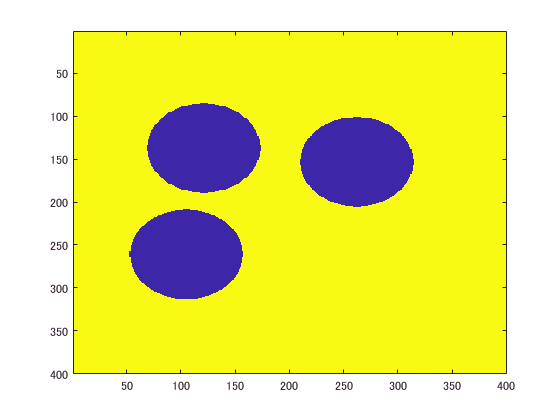

figure;
im = imagesc(medium.sound_speed);

% imshow(im);
% [center, radi] = imfindcircles(im, [20, 50]);

あとでこの図は２分割する．

%% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 平均音速算出(配列定義) Group1 Erate = 6:2:20
tof_cell  = zeros(200,100,20,5,5);%{Receiver, Transmitter, ERate, IRate, Num, }
aveSOS = zeros(20,5,5);%{ERate, IRate, Num}
steSOS = zeros(20,5,5);
for i = 1:5
    if i == 2
        continue;
    end
    if i == 3
        continue;
    end
    cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_04_27_analyzeLipidModel')
    myfilename = sprintf('2018_04_27_TOFdata_Group1ERate5IRate02Num%d-2', i);
    load(myfilename,'tof_data');
    tof_cell(:,:,5,1,i) = tof_data;
end
for i = 2:3
    cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_04_27_analyzeLipidModel')
    myfilename = sprintf('2018_04_27_TOFdata_Group1ERate5IRate02Num%d-2', i);
    load(myfilename,'tof_data');
    tof_cell(:,:,5,1,i) = tof_data;
end
for i = 1:4
    if i == 2
        continue;
    end
    cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_04_27_analyzeLipidModel')
    myfilename = sprintf('2018_04_27_TOFdata_Group1ERate%dIRate02Num3-2', i);
    load(myfilename,'tof_data');
    tof_cell(:,:,i,1,3) = tof_data;
end
cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_04_27_analyzeLipidModel')
myfilename = sprintf('2018_04_27_TOFdata_Group1ERate2IRate02Num3-2');
load(myfilename,'tof_data');
tof_cell(:,:,2,1,3) = tof_data;
for i = 2:4
    cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_04_27_analyzeLipidModel')
    myfilename = sprintf('2018_04_27_TOFdata_Group1ERate5IRate0%dNum3-2', i*2);
    load(myfilename,'tof_data');
    tof_cell(:,:,5,i,3) = tof_data;
end
cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_04_27_analyzeLipidModel')
myfilename = sprintf('2018_04_27_TOFdata_Group1ERate5IRate10Num3-2');
load(myfilename,'tof_data');
tof_cell(:,:,5,5,3) = tof_data;
for i = 6:2:20
    cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_04_27_analyzeLipidModel')
    myfilename = sprintf('2018_04_27_TOFdata_Group1ERate%dIRate02Num3-2', i);
    load(myfilename,'tof_data');
    tof_cell(:,:,i,1,3) = tof_data;
end

myfilename = sprintf('2018_04_27_Group1dallTOFdata_matrix_temp-2');
save(myfilename,'tof_cell');
%% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 平均音速算出（メイン） Group1 Erate = 6:2:20
cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_04_27_analyzeLipidModel')
myfilename = sprintf('2018_04_27_Group1dallTOFdata_matrix_temp-2');
load(myfilename,'tof_cell');
cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_02_28_-kwave');
myfilename = sprintf('2018_04_26_Group1ERate5IRate02Num3-2');
cd(myfilename);
load('kgrid.mat')
param = makeParam( 0.125,0.125,400,400,0 );
param.source.point_map = cast(linspace(1,100,100),'int8');
t_size = 40.e-3;
t_num = 200;%トランスデューサ数
t_pos = zeros(2, t_num);%センサ位置
t_pos(1,1:t_num/2) = -t_size/2:t_size/(t_num/2-1):t_size/2 ;%素子水平方向距離[m]
t_pos(2,1:t_num/2) = t_size/2;
t_pos(1,t_num/2+1:t_num) = t_pos(1,1:t_num/2);
t_pos(2,t_num/2+1:t_num) = -t_size/2;
sensor.mask=t_pos;
leng = zeros(1,100);

for i = 1:5
    [Min,ind]= min(tof_cell(101:end,:,i,1,3));
    ind = ind+100;
    for j = 1: t_num/2
        leng(1,j) = norm(t_pos(:,j)-t_pos(:,ind(1,j)));
    end
  
    aveSOS(i,1,3) = sum(leng./Min)/(t_num/2);
    steSOS(i,1,3) = std(leng./Min,0,2)/sqrt(t_num/2);
end
for i = 6:2:20
    [Min,ind]= min(tof_cell(101:end,:,i,1,3));
    ind = ind+100;
    for j = 1: t_num/2
        leng(1,j) = norm(t_pos(:,j)-t_pos(:,ind(1,j)));
    end
    aveSOS(i,1,3) =sum(leng./Min)/(t_num/2);
    steSOS(i,1,3) =std(leng./Min,0,2)/sqrt(t_num/2);
end
for i = 1:5
    [Min,ind]= min(tof_cell(101:end,:,5,1,i));
    ind = ind+100;
    for j = 1: t_num/2
        leng(1,j) = norm(t_pos(:,j)-t_pos(:,ind(1,j)));
    end
    aveSOS(5,1,i) = sum(leng./Min)/(t_num/2);
    steSOS(5,1,i) =std(leng./Min,0,2)/sqrt(t_num/2);
end
for i = 1:5
    [Min,ind]= min(tof_cell(101:end,:,5,i,3));
    ind = ind+100;
    for j = 1: t_num/2
        leng(1,j) = norm(t_pos(:,j)-t_pos(:,ind(1,j)));
    end
    aveSOS(5,i,3) = sum(leng./Min)/(t_num/2);
    steSOS(5,i,3) = std(leng./Min,0,2)/sqrt(t_num/2);
end
cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_04_27_analyzeLipidModel')
myfilename = sprintf('2018_04_28_Group1aveSOS_temp-2');
save(myfilename,'aveSOS');
myfilename = sprintf('2018_04_28_Group1steSOS_temp-2');
save(myfilename,'steSOS');

%% 上の振り方のまま別の平均音速算出法を試す．
%対向する受信素子において，その伝わるパワーの半分が伝わった時間を元に平均音速を算出する．
cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_02_28_-kwave');
myfilename = sprintf('2018_04_26_Group1ERate5IRate02Num3-2');
cd(myfilename);
load('kgrid.mat')
param = makeParam( 0.125,0.125,400,400,0 );
param.source.point_map = cast(linspace(1,100,100),'int8');
t_size = 40.e-3;
t_num = 200;%トランスデューサ数
t_pos = zeros(2, t_num);%センサ位置
t_pos(1,1:t_num/2) = -t_size/2:t_size/(t_num/2-1):t_size/2 ;%素子水平方向距離[m]
t_pos(2,1:t_num/2) = t_size/2;
t_pos(1,t_num/2+1:t_num) = t_pos(1,1:t_num/2);
t_pos(2,t_num/2+1:t_num) = -t_size/2;
sensor.mask=t_pos;
leng = 40 * 1e-3;
dt = kgrid.dt;
aveSOS = zeros(20,1);
steSOS = zeros(20,1);
for i = 2:2:20
    cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_02_28_-kwave');
    myfilename = sprintf('2018_04_26_Group1ERate%dIRate02Num3-2',i);
    cd(myfilename);
    load('rfdata')
    L = length(rfdata(:,1,1));
    store_rf = zeros(L,t_num/2);
    str_rf_abs = zeros(L,t_num/2);
    total_str_rf_abs = zeros(t_num/2);
    str_half_t = zeros(t_num/2,1);
    
    for j = 1: t_num/2
        check_tmp = 2;
        store_rf(:,j,i) = rfdata(:,100+j,j);
        str_rf_abs(:,j,i) = abs(store_rf(:,j,i));
        total_str_rf_abs(j,i) = sum(str_rf_abs(:,j,i));
        total_tmp = total_str_rf_abs(j,i);
        while sum(str_rf_abs(1:check_tmp,j,i)) < 0.5*total_tmp
            check_tmp = check_tmp+1;
        end
        str_half_t(j,i) = check_tmp * dt;
    end
    aveSOS(i,1) = sum(leng./str_half_t(:,i))/(t_num/2);
    steSOS(i,1) = std(leng./str_half_t(:,i))/sqrt(t_num/2);
end
cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_04_27_analyzeLipidModel')
myfilename = sprintf('2018_04_28_Group1aveSOS2_temp-2');
save(myfilename,'aveSOS');
myfilename = sprintf('2018_04_28_Group1steSOS2_temp-2');
save(myfilename,'steSOS');

## シミュレーション結果による最短経路と，伝播経路を直線と仮定した場合での最短経路（手計算）との比較．

上の図は少々複雑なので，簡単なEMCL２個パターンで考えてみる．

cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_02_28_-kwave');
myfilename = sprintf('2018_04_26_Group1ERate5IRate02Num2-2');
cd(myfilename);
load('kgrid.mat')
i = 5;

figure;
cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\medium\2018_04_26_randomScatter')
myfilename = sprintf('Group1ERate%dIRate02Num2-2', i);
load(myfilename);
cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_04_27_analyzeLipidModel')
myfilename = sprintf('2018_04_27_TOFdata_Group1ERate%dIRate02Num2-2',i);
load(myfilename)


param = makeParam( 0.125,0.125,400,400,0 );
param.source.point_map = cast(linspace(1,100,100),'int8');
t_size = 40.e-3;
t_num = 200;%トランスデューサ数
t_pos = zeros(2, t_num);%センサ位置
t_pos(1,1:t_num/2) = -t_size/2:t_size/(t_num/2-1):t_size/2 ;%素子水平方向距離[m]
t_pos(2,1:t_num/2) = t_size/2;
t_pos(1,t_num/2+1:t_num) = t_pos(1,1:t_num/2);
t_pos(2,t_num/2+1:t_num) = -t_size/2;
sensor.mask=t_pos;


[Min,ind]= min(tof_data(101:end,:));
ind = ind+100;
% for j = 1:100
%     tof_data(ind(1,j),j) = 0;
% end

subplot(1,2,1);
imagesc(kgrid.x_vec*1000,kgrid.y_vec*1000,medium.sound_speed);
axis equal
axis tight
hold on
scatter(t_pos(2,:)*1000,t_pos(1,:)*1000,'rs','filled');
xlabel('y-axis[mm]')
ylabel('x-axis[mm]')

hold on
for i = 1:length(ind)
%     plot([x0;x1],[y0;y1]);
    plot([t_pos(2,i)*1000;t_pos(2,ind(i))*1000],[t_pos(1,i)*1000;t_pos(1,ind(i))*1000],'.-k','LineWidth',0.01);
end

hold off
subplot(1,2,2);


imagesc(1:100,1:100,tof_data(101:end,:));
hold on 
scatter(1:100,ind(1,1:100)-100,3,'filled','k','o')
xlabel('transmitter')
ylabel('receiver')
colorbar;
c = colorbar;
c.Label.String = 'arrival time[s]';
axis tight
axis equal

% titlename = sprintf('Group1ERate%dIRate02Num3',i);
% axes;
% title(titlename);
% axis off;

exportfig('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_04_27_analyzeLipidModel\2018_05_01_Group1ERate20IRate02Num3_Compare-2-ss','png',[650,200]);

## シミュレーション結果による最短経路と，伝播経路を直線と仮定した場合での最短経路（手計算）との比較．

上の図は少々複雑なので，簡単なEMCL1個パターンで試してみる．

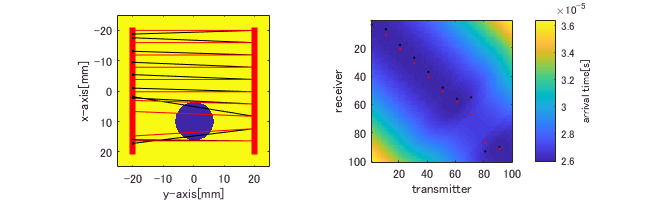

cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_02_28_-kwave');
myfilename = sprintf('2018_04_26_Group1ERate5IRate02Num1-2');
cd(myfilename);
load('kgrid.mat')
i = 5;

figure;
cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\medium\2018_04_26_randomScatter')
myfilename = sprintf('Group1ERate%dIRate02Num1-2', i);
load(myfilename);
cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_04_27_analyzeLipidModel')
myfilename = sprintf('2018_04_27_TOFdata_Group1ERate%dIRate02Num1-2',i);
load(myfilename)


param = makeParam( 0.125,0.125,400,400,0 );
param.source.point_map = cast(linspace(1,100,100),'int8');
t_size = 40.e-3;
t_num = 200;%トランスデューサ数
t_pos = zeros(2, t_num);%センサ位置
t_pos(1,1:t_num/2) = -t_size/2:t_size/(t_num/2-1):t_size/2 ;%素子水平方向距離[m]
t_pos(2,1:t_num/2) = t_size/2;
t_pos(1,t_num/2+1:t_num) = t_pos(1,1:t_num/2);
t_pos(2,t_num/2+1:t_num) = -t_size/2;
sensor.mask=t_pos;


[Min,ind]= min(tof_data(101:end,:));
ind = ind+100;
% for j = 1:100
%     tof_data(ind(1,j),j) = 0;
% end

subplot(1,2,1);
imagesc(kgrid.x_vec*1000,kgrid.y_vec*1000,medium.sound_speed);
axis equal
axis tight
hold on
scatter(t_pos(2,:)*1000,t_pos(1,:)*1000,'rs','filled');
xlabel('y-axis[mm]')
ylabel('x-axis[mm]')

hold on
for i = 1:10:length(ind)
%     plot([x0;x1],[y0;y1]);
    plot([t_pos(2,i)*1000;t_pos(2,ind(i))*1000],[t_pos(1,i)*1000;t_pos(1,ind(i))*1000],'.-k','LineWidth',0.01);
end
plot([t_pos(2,61)*1000;t_pos(2,158)*1000],[t_pos(1,61)*1000;t_pos(1,158)*1000],'.-r','LineWidth',0.01);
plot([t_pos(2,71)*1000;t_pos(2,167)*1000],[t_pos(1,71)*1000;t_pos(1,167)*1000],'.-r','LineWidth',0.01);
plot([t_pos(2,81)*1000;t_pos(2,187)*1000],[t_pos(1,81)*1000;t_pos(1,187)*1000],'.-r','LineWidth',0.01);
for i = 1:10:51
%     plot([x0;x1],[y0;y1]);
    plot([t_pos(2,i)*1000;t_pos(2,100+i)*1000],[t_pos(1,i)*1000;t_pos(1,i+100)*1000],'.-r','LineWidth',0.01);
end
i=91;
plot([t_pos(2,i)*1000;t_pos(2,100+i)*1000],[t_pos(1,i)*1000;t_pos(1,i+100)*1000],'.-r','LineWidth',0.01);
hold off
subplot(1,2,2);


imagesc(1:100,1:100,tof_data(101:end,:));
hold on 
scatter(1:10:100,ind(1,1:10:100)-100,3,'filled','k','o')
scatter(1:10:51,(101:10:151)-100,3,'filled','r','o')
scatter(61,58,3,'filled','r','o')
scatter(71,67,3,'filled','r','o')
scatter(81,87,3,'filled','r','o')
scatter(91,91,3,'filled','r','o')
xlabel('transmitter')
ylabel('receiver')
colorbar;
c = colorbar;
c.Label.String = 'arrival time[s]';
axis tight
axis equal

% titlename = sprintf('Group1ERate%dIRate02Num3',i);
% axes;
% title(titlename);
% axis off;
exportfig('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_05_17_handValidationLipidModel\2018_05_20_P7-9_Comp','png',[650,200]);

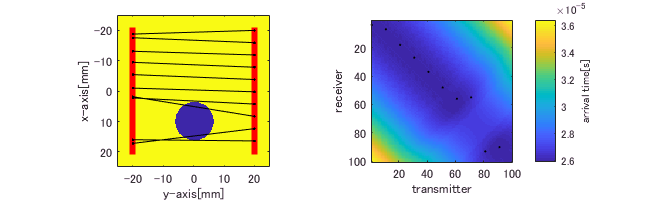

cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_02_28_-kwave');
myfilename = sprintf('2018_04_26_Group1ERate5IRate02Num1-2');
cd(myfilename);
load('kgrid.mat')
i = 5;

figure;
cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\medium\2018_04_26_randomScatter')
myfilename = sprintf('Group1ERate%dIRate02Num1-2', i);
load(myfilename);
cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_04_27_analyzeLipidModel')
myfilename = sprintf('2018_04_27_TOFdata_Group1ERate%dIRate02Num1-2',i);
load(myfilename)


param = makeParam( 0.125,0.125,400,400,0 );
param.source.point_map = cast(linspace(1,100,100),'int8');
t_size = 40.e-3;
t_num = 200;%トランスデューサ数
t_pos = zeros(2, t_num);%センサ位置
t_pos(1,1:t_num/2) = -t_size/2:t_size/(t_num/2-1):t_size/2 ;%素子水平方向距離[m]
t_pos(2,1:t_num/2) = t_size/2;
t_pos(1,t_num/2+1:t_num) = t_pos(1,1:t_num/2);
t_pos(2,t_num/2+1:t_num) = -t_size/2;
sensor.mask=t_pos;


[Min,ind]= min(tof_data(101:end,:));
ind = ind+100;
% for j = 1:100
%     tof_data(ind(1,j),j) = 0;
% end

subplot(1,2,1);
imagesc(kgrid.x_vec*1000,kgrid.y_vec*1000,medium.sound_speed);
axis equal
axis tight
hold on
scatter(t_pos(2,:)*1000,t_pos(1,:)*1000,'rs','filled');
xlabel('y-axis[mm]')
ylabel('x-axis[mm]')

hold on
for i = 1:10:length(ind)
%     plot([x0;x1],[y0;y1]);
    plot([t_pos(2,i)*1000;t_pos(2,ind(i))*1000],[t_pos(1,i)*1000;t_pos(1,ind(i))*1000],'.-k','LineWidth',0.01);
end
% plot([t_pos(2,61)*1000;t_pos(2,158)*1000],[t_pos(1,61)*1000;t_pos(1,158)*1000],'.-r','LineWidth',0.01);
% plot([t_pos(2,71)*1000;t_pos(2,167)*1000],[t_pos(1,71)*1000;t_pos(1,167)*1000],'.-r','LineWidth',0.01);
% plot([t_pos(2,81)*1000;t_pos(2,187)*1000],[t_pos(1,81)*1000;t_pos(1,187)*1000],'.-r','LineWidth',0.01);
% for i = 1:10:51
%     plot([x0;x1],[y0;y1]);
%     plot([t_pos(2,i)*1000;t_pos(2,100+i)*1000],[t_pos(1,i)*1000;t_pos(1,i+100)*1000],'.-r','LineWidth',0.01);
% end
% i=91;
% plot([t_pos(2,i)*1000;t_pos(2,100+i)*1000],[t_pos(1,i)*1000;t_pos(1,i+100)*1000],'.-r','LineWidth',0.01);
hold off
subplot(1,2,2);


imagesc(1:100,1:100,tof_data(101:end,:));
hold on 
scatter(1:10:100,ind(1,1:10:100)-100,3,'filled','k','o')
% scatter(1:10:51,(101:10:151)-100,3,'filled','r','o')
% scatter(61,58,3,'filled','r','o')
% scatter(71,67,3,'filled','r','o')
% scatter(81,87,3,'filled','r','o')
% scatter(91,91,3,'filled','r','o')
xlabel('transmitter')
ylabel('receiver')
colorbar;
c = colorbar;
c.Label.String = 'arrival time[s]';
axis tight
axis equal

% titlename = sprintf('Group1ERate%dIRate02Num3',i);
% axes;
% title(titlename);
% axis off;
exportfig('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_05_17_handValidationLipidModel\2018_05_20_P1-10','png',[650,200]);